# Homework 4

# MAE 384

# Zachary Van Horn 1216978217

## Q1:

Problem Statement: I am to find the discrete fourier transformation for a set of data of vibrations over a set time to find a good intepolation of the data. 

Solution:

%HW Prob 1
clc; clear; close all;

T = 0.5;
y = [3.5 6.0 11.7 14.1 15.3 8.5 8.0 9.1 10.1 10.9 8.6 1.05 -1.9 -3.2 -4.7 -4.8 -3.9 -1.7 0.5 3.5];
N = length(y);
w = 2*pi/T;
t = linspace(0,T,N);
k = 0:N-1;

%A
a0 = (1/N)*sum(y);
ak = [];
bk = [];

for j = 1:length(k)
    ak1 = [];
    bk1 = [];
    for i = 1:N
        ak1 = [ak1 y(i).*cos(k(j).*w.*t(j))];
        bk1 = [bk1 y(i).*sin(k(j).*w.*t(j))];
    end
end
ak = [ak (2/N)*sum(ak1)];
bk = [bk (2/N)*sum(bk1)];

%B
ck = sqrt((ak.^2) * (bk.^2));
phi = atan(-bk/ak);

%C
figure(1);
hold on
plot(t,y,ak1,y,bk1,y)
xlabel('Time');
ylabel('Amplitude');
legend('Original','Ak','Bk');
hold off

Results: 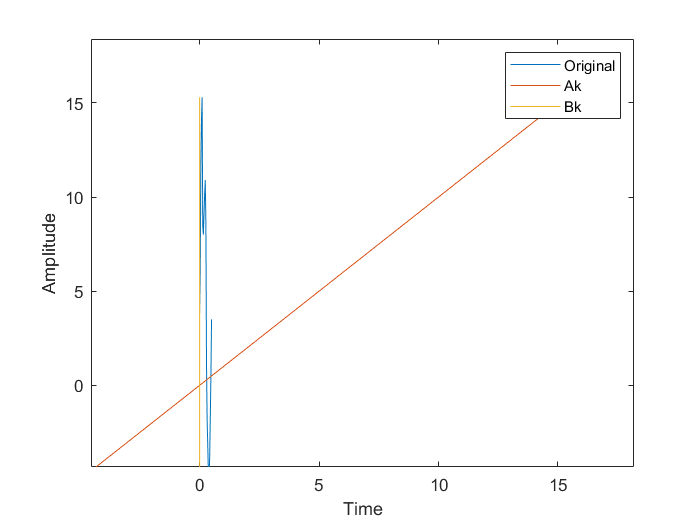

Discussion: I would not do it this method, because it's clear I did it wrong and I also believe it is more complicated than other intepolation methods. 

## Q2:

Problem Statement: I am to find the stability limit and trucation error using the runge katta 4th order formula. 

Solution:

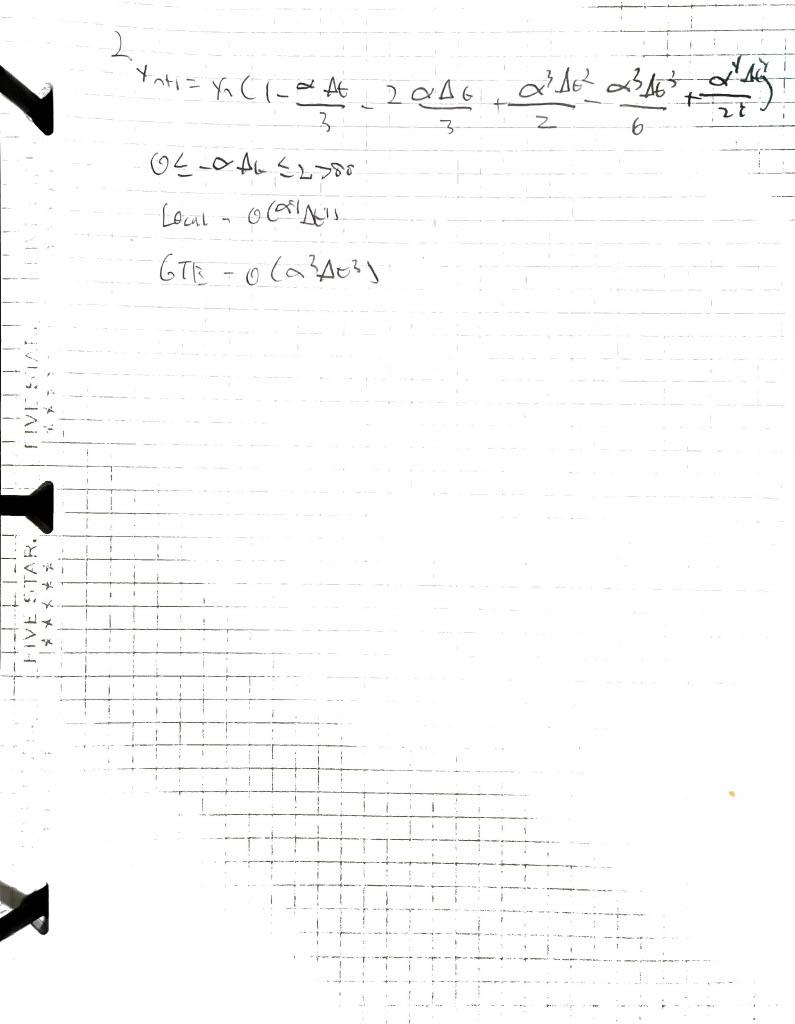

## Q3:

Problem Statement: I am to solve a differntial equation over the length of a vector through various methods.

Solution: I solved the first way by seperating the variables by hand like how I learned it in MAT 275. I used the Euler explicit formula then the runge katta and then the Matlab function ode45. 

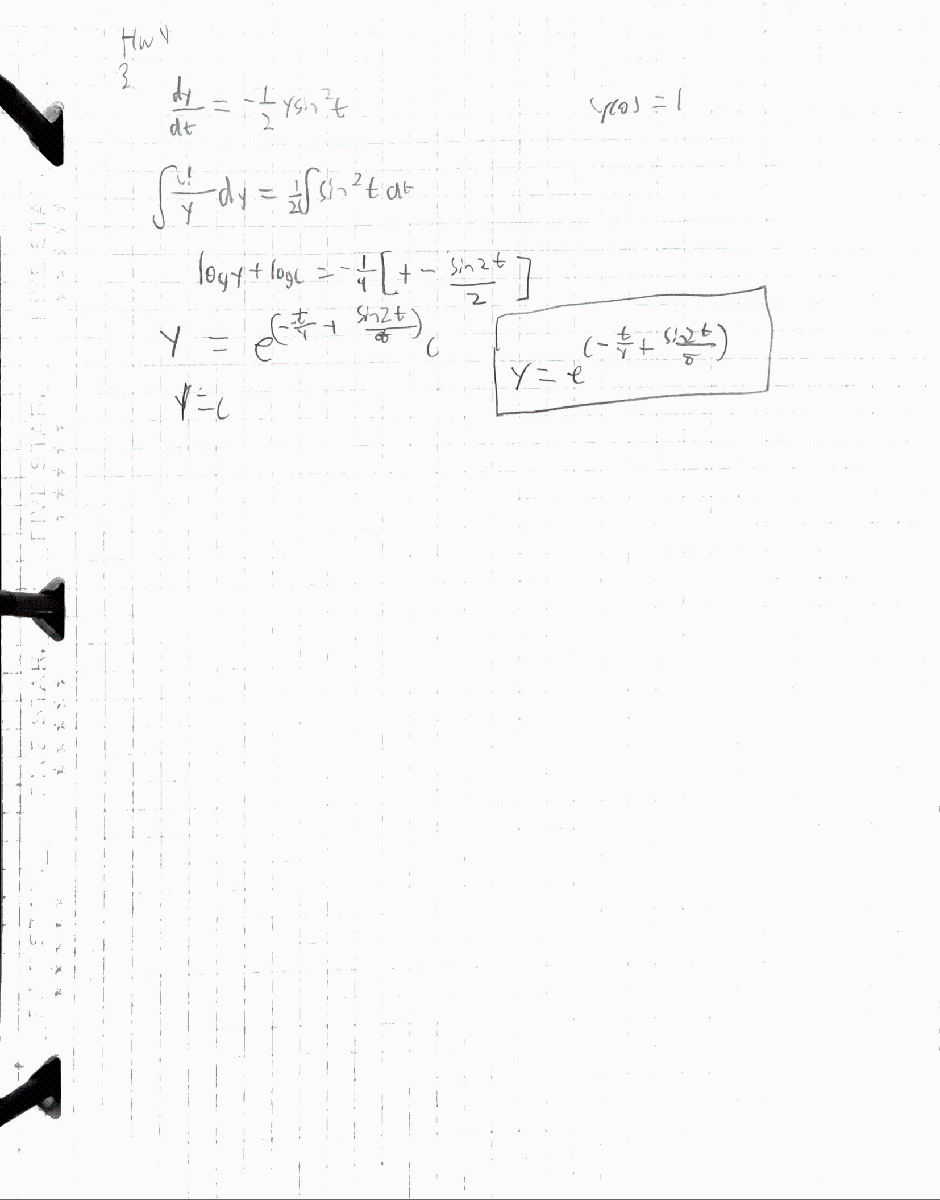

The Euler Explicit code: I created an upper and lower bound, and then created some steps between the bounds. I then added a for loop where it adds a step to each bound. 

% %Explicit Euler method
% %Explicit Euler method
% function [t,y] = eulerexpHW4(ODE,a,b,step,yinitial)
% t(1) = a; 
% y(1) = yinitial; 
% Nee = (b-a)/step; %Number of steps
% 
%     for i = 1:Nee
%         t(i+1) = t(i) + step;
%         y(i+1) = y(i) + ODE(t(i),y(i))*step;
%     end
% end

The Runge Katta Code: I inputted the Runge Katta formula into a for loop to go through a certain amount of iterations to get an answer at each given.

%4th Order Runge Katta

% function[t,y] = rungekatta4HW4(ODE,a,b,step,yinitial)
%     t(1) = a;
%     y(1) = yinitial;
%     Nrk = (b-a)/step;
% 
%     for i = 1:Nrk
%         t(i+1) = t(i) + step;
%         k1 = ODE(t(i),y(i));
%         xhalf = t(i) + step/2;
%         yhalf = y(i) + k1*step/2;
%         k2 = ODE(xhalf,yhalf);
%         yk2 = y(i) + k2*step/2;
%         k3 = ODE(xhalf,yk2);
%         yk3 = y(i) +k3*step;
%         k4 = ODE(t(i+1),yk3);
%         y(i+1) = y(i)+ (k1 + 2*k2 + 2*k3 +k4) * (step/6);
%     end
% end

 ode45 Code: I used the ode45 matlab function

[to,yo] =  ode45(@hw4ode,t,yinitial);

Results: 

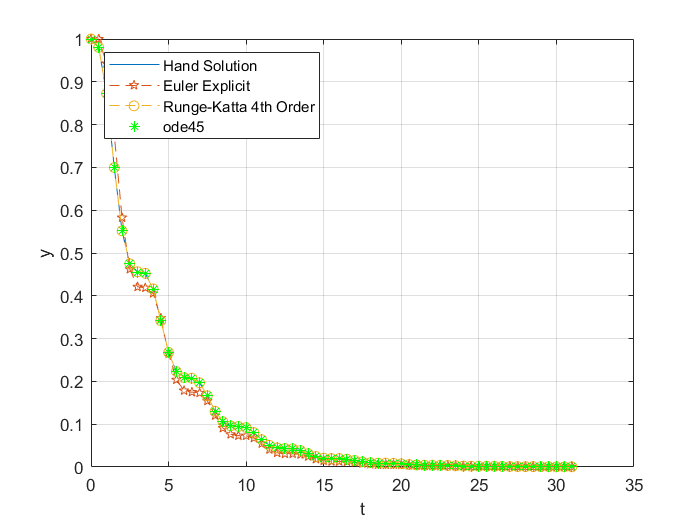

Discussion: The euler explicit method produced the least accurate estimation compared to the others. While the ode45 function created the most accruate estimation of the ODE, with the Runge-Katta method close to ode45 but not as accurate. 

Appendix: 

% %HW4 Q3
% clc; clear; close all;
% 
% %Bounds and givens
% step = 0.5;
% t = 0:step:10*pi;
% a = 0; %Lower Bound
% b = 10*pi; %Upper Bound
% yinitial = 1; %Initial Condition
% 
% %Via hand solution
% ysep = exp(-t/4+(sin(2*t)/8));
% 
% %Euler Explicit
% [te,ye] = eulerexpHW4(@hw4ode,a,b,step,yinitial);
% 
% %Runge Katta
% [tr,yr] = rungekatta4HW4(@hw4ode,a,b,step,yinitial);
% 
% %ODE 45
% [to,yo] =  ode45(@hw4ode,t,yinitial);
% 
% %Plot to Compare
% figure(2)
% plot(t,ysep)
% grid on
% hold on
% plot(te,ye,'--p')
% plot(tr,yr,'--o')
% plot(to,yo,'*g')
% xlabel('t');
% ylabel('y');
% legend('Hand Solution','Euler Explicit','Runge-Katta 4th Order','ode45','location','NW')
% grid on

%Function to solve ODE

% function dydt = hw4ode(t,y) 
%     dydt = (-0.5)*y*(sin(t))^2;
% end